# 02B. Numerical integration

## Mingyang Lu

## 01/07/2024

Here, we illustrate numerical methods to solve ODEs in the context of the circuit with a constitutively expressed gene:


$$$$\frac{dX}{dt} = f(x) \equiv g- kX$$$$


### Euler method

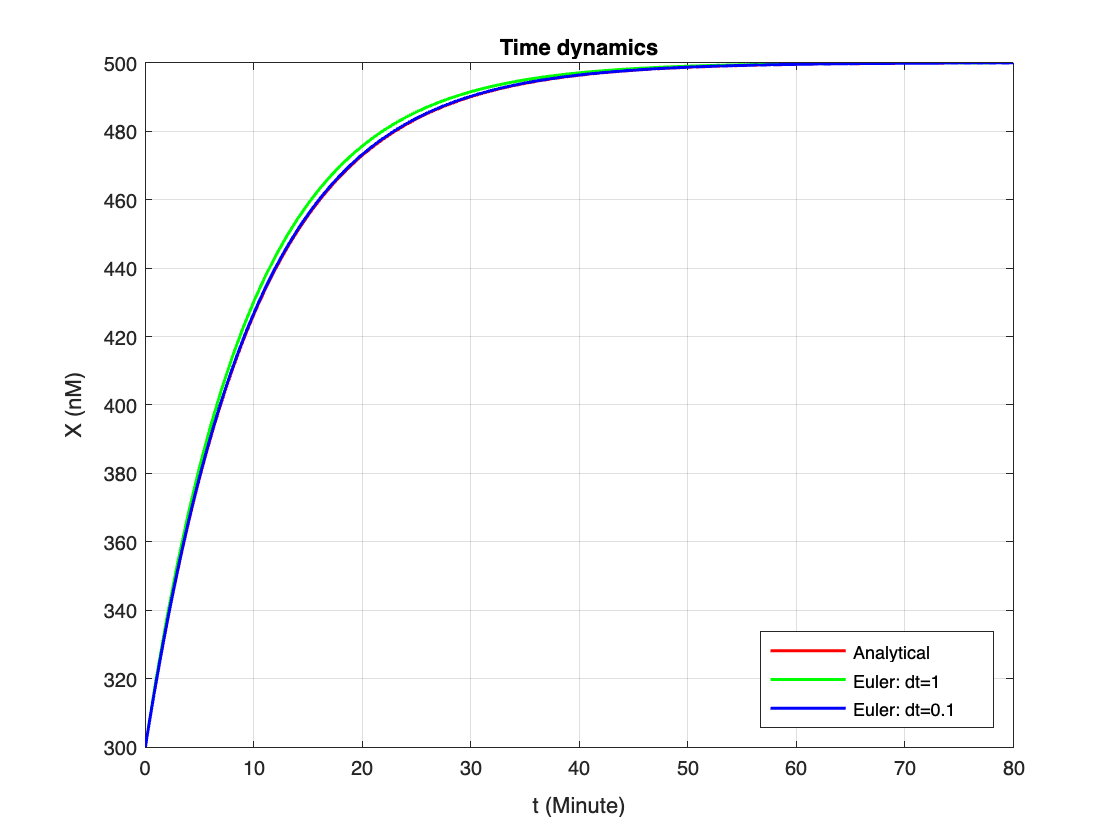

% Time points for plotting
t_all = 0:0.1:80;

% Model parameters
g = 50;
k = 0.1;

% Numerical solution using Euler method with different time step sizes
results1 = Euler(@dX, 300, 80, 1, g, k);
results2 = Euler(@dX, 300, 80, 0.1, g, k);

% Plotting
figure;
plot(t_all, ode1(300, t_all, g, k), 'r', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
hold on;
plot(results1(:, 1), results1(:, 2), 'g', 'LineWidth', 1.5, 'DisplayName', 'Euler: dt=1');
plot(results2(:, 1), results2(:, 2), 'b', 'LineWidth', 1.5, 'DisplayName', 'Euler: dt=0.1');

xlabel('t (Minute)');
ylabel('X (nM)');
xlim([0, 80]);
ylim([300, 500]);
legend('Location', 'southeast');
title('Time dynamics');
grid on;
hold off;

Zoom-in view of the time trajectories

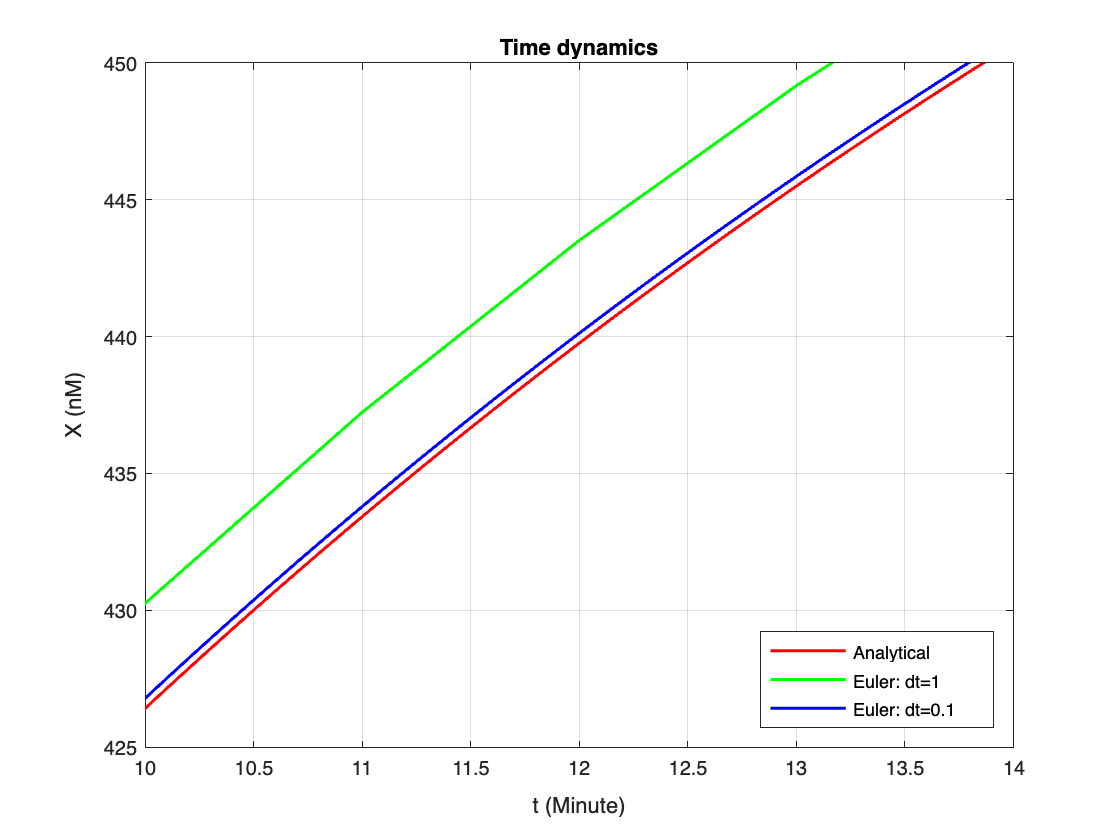

% Plotting
figure;
plot(t_all, ode1(300, t_all, g, k), 'r', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
hold on;
plot(results1(:, 1), results1(:, 2), 'g', 'LineWidth', 1.5, 'DisplayName', 'Euler: dt=1');
plot(results2(:, 1), results2(:, 2), 'b', 'LineWidth', 1.5, 'DisplayName', 'Euler: dt=0.1');

xlabel('t (Minute)');
ylabel('X (nM)');
xlim([10, 14]);
ylim([425, 450]);
legend('Location', 'southeast');
title('Time dynamics');
grid on;
hold off;

### Heun `method`[¶](http://localhost:8888/notebooks/02B.ipynb#Heun-method)

% Numerical solution using Heun method
results3 = Heun(@dX, 300, 80, 1, g, k);

### 2nd-order Runge-Kutta method (RK2)

% Numerical solution using RK2 method
results4 = RK2(@dX, 300, 80, 1, g, k);

### Fourth order Runge-Kutta method (RK4)[¶](http://localhost:8888/notebooks/02B.ipynb#Fourth-order-Runge-Kutta-method-(RK4))

% Numerical solution using RK2 method
results5 = RK4(@dX, 300, 80, 1, g, k);

## Comparisons between various integrators

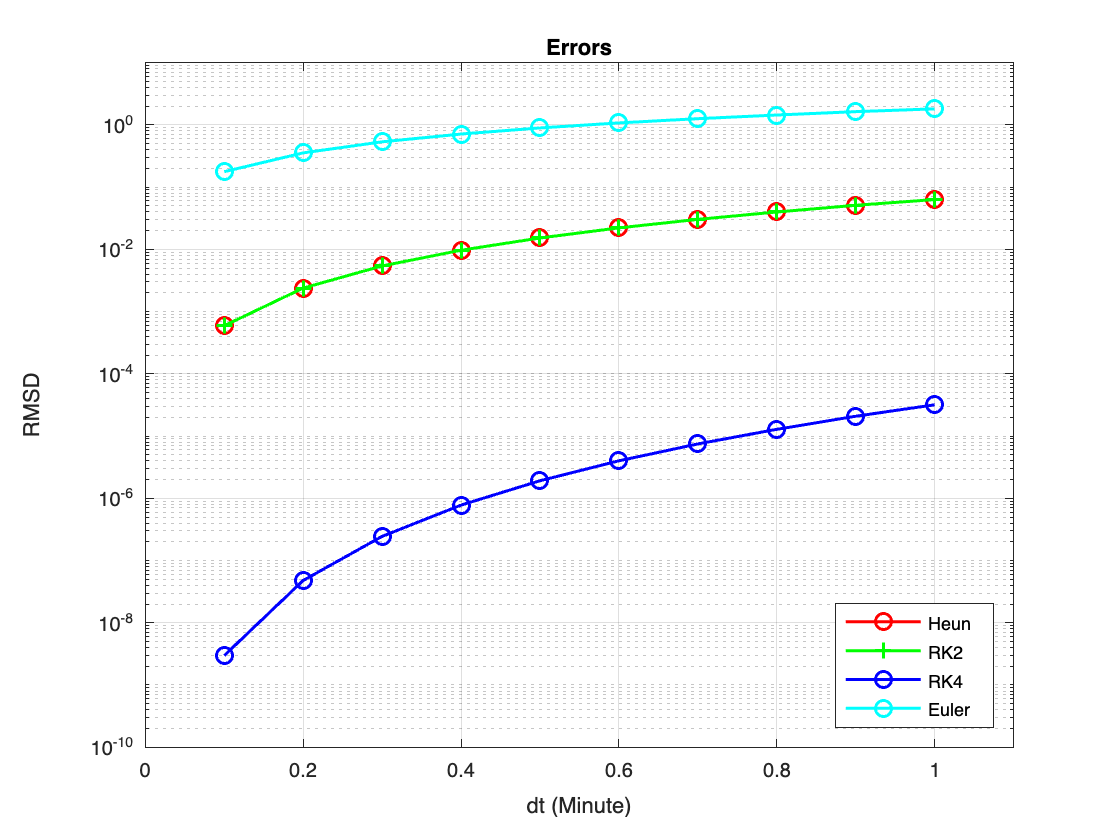

% Comparison of methods using different time step sizes
dt_all = 0.1:0.1:1.0;

errors_Euler = zeros(size(dt_all));
errors_Heun = zeros(size(dt_all));
errors_RK2 = zeros(size(dt_all));
errors_RK4 = zeros(size(dt_all));

% Model parameters
g = 50;
k = 0.1;
t_total = 80;
% Initial condition
X0 = 300;

ind = 1;
for dt = dt_all
    t_all = 0:dt:t_total;  % time points to compute

    results_ode = ode1(X0, t_all, g, k);  % exact solutions
    results_Heun = Heun(@dX, X0, t_total, dt, g, k); % dX/dt = g - k * X
    results_RK2 = RK2(@dX, X0, t_total, dt, g, k);
    results_RK4 = RK4(@dX, X0, t_total, dt, g, k);
    results_Euler = Euler(@dX, X0, t_total, dt, g, k);

    errors_Heun(ind) = rmsd(results_ode', results_Heun(:, 2));
    errors_RK2(ind) = rmsd(results_ode', results_RK2(:, 2));
    errors_RK4(ind) = rmsd(results_ode', results_RK4(:, 2));
    errors_Euler(ind) = rmsd(results_ode', results_Euler(:, 2));
    ind = ind + 1;
end

figure;
plot(dt_all, errors_Heun, 'o-', 'Color', [1 0 0], 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'Heun');
hold on;
plot(dt_all, errors_RK2, '+-', 'Color', [0 1 0], 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'RK2');
plot(dt_all, errors_RK4, 'o-', 'Color', [0 0 1], 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'RK4');
plot(dt_all, errors_Euler, 'o-', 'Color', [0 1 1], 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'Euler');

set(gca, 'XScale', 'linear', 'YScale', 'log');
xlabel('dt (Minute)');
ylabel('RMSD');
xlim([0, 1.1]);
ylim([1e-10, 10]);

legend('Location', 'southeast')
title('Errors');
grid on;
hold off;

### Backward Euler method

The EUler method is an explicit method, where $X_{n+1} =X_n +hf(X_n ,t)$. In the current method, we have

$$$X_{n+1} = X_n + h(g-kX_n) = hg + (1-hk)X_n $$$.

The integrator becomes unstable when $h>\frac{1}{k}$.

The backward Euler method takes the formula:

$$$X_{n+1} = X_n + hf(X_{n+1}, t_{n+1})$$$.

Here, $f(N_{n+1} ,t_{n+1} )=g-kX_{n+1}$. Thus,


$$X_{n+1} =\frac{X_n +hg}{1+hk}$$


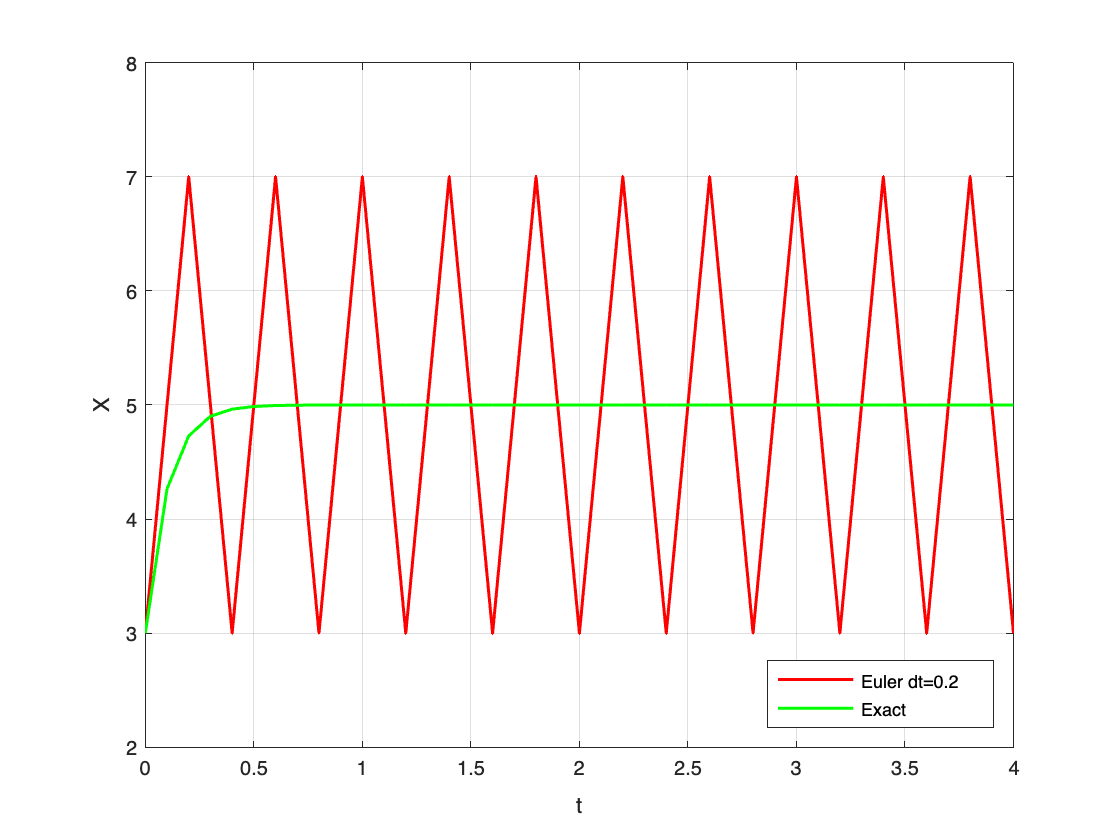

% Given parameters
g = 50;
k = 10;
t_total = 4;

% Time points to plot
t_all = 0:0.1:t_total;

% Run Euler simulation
result_euler = Euler(@dX, 3, t_total, 0.2, g, k);

% Compute the analytical solution
result_exact = [t_all', ode1(3, t_all, g, k)'];

% Plotting the outcomes
figure;
plot(result_euler(:, 1), result_euler(:, 2), 'r-', 'LineWidth', 1.5, 'DisplayName', 'Euler dt=0.2');
hold on;
plot(result_exact(:, 1), result_exact(:, 2), 'g-', 'LineWidth', 1.5, 'DisplayName', 'Exact');

xlabel('t');
ylabel('X');
xlim([0, t_total]);
ylim([2, 8]);

legend('Location', 'southeast');
grid on;
hold off;

The backward Euler method takes the formula:

$X_{n+1} =X_n +hf(X_{n+1} ,t_{n+1} )$.

Here, $f(N_{n+1} ,t_{n+1} )=g-kX_{n+1}$. Thus,

$X_{n+1} =\frac{X_n +hg}{1+hk}$.

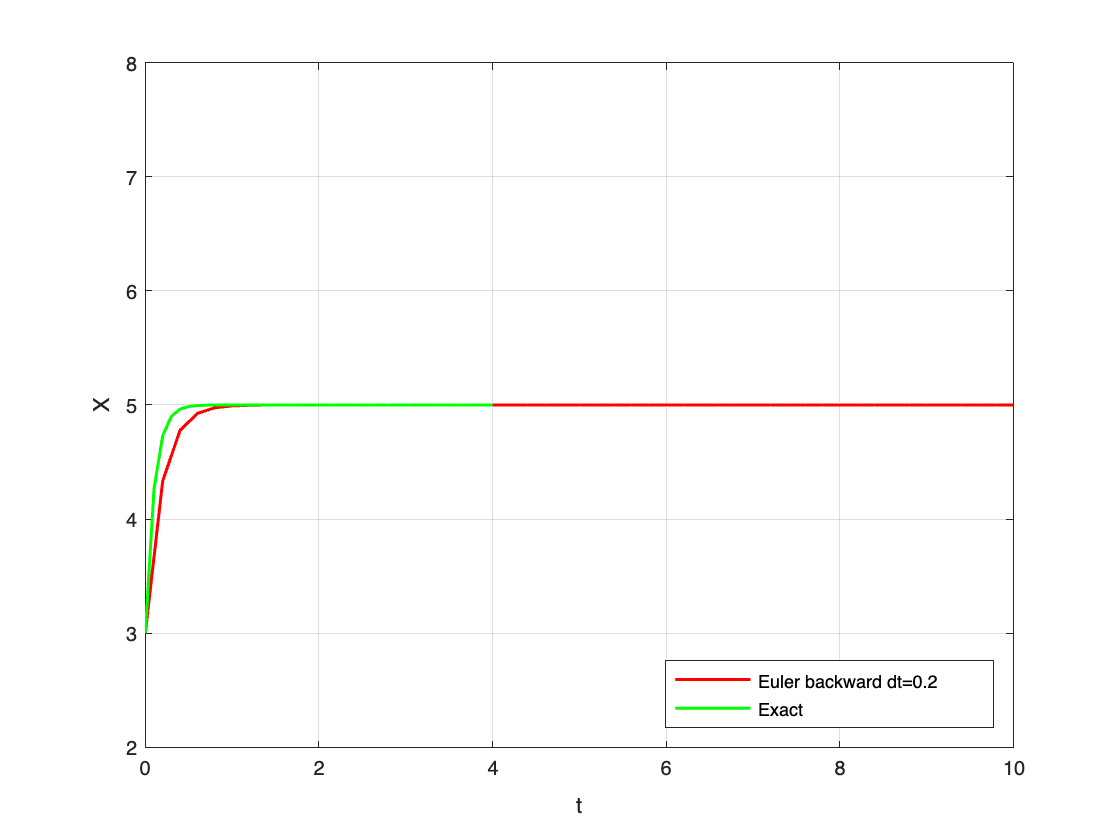

% Run Euler backward simulation
t_total = 10;  % Adjust the total simulation time accordingly
result_euler_backward = euler_backward_1g(0, 3, t_total, 0.2, g, k);

% Plotting the outcomes
figure;
plot(result_euler_backward(:, 1), result_euler_backward(:, 2), 'r-', 'LineWidth', 1.5, 'DisplayName', 'Euler backward dt=0.2');
hold on;
plot(result_exact(:, 1), result_exact(:, 2), 'g-', 'LineWidth', 1.5, 'DisplayName', 'Exact');

xlabel('t');
ylabel('X');
xlim([0, t_total]);
ylim([2, 8]);

legend('Location', 'southeast');
grid on;
hold off;

### Define MATLAB functions

1. Generic function of Euler Method for 1 1-variable system

% Euler is a generic function of Euler method for simulating ODE numerically
% The function works for a 1-variable system
% varargin is used to pass any variable number of arguments to the function

function results = Euler(derivs, X0, t_total, dt, varargin)
    t_all = 0:dt:t_total;
    n_all = length(t_all);

    X_all = zeros(1, n_all);
    X_all(1) = X0;
    
    for i = 2:n_all
        X_all(i) = X_all(i - 1) + dt * derivs(t_all(i - 1), X_all(i - 1), varargin{:});
    end
    
    results = [t_all', X_all'];  % Output matrix of t & X(t) for all time steps
end

2. Analytical solution for the ODE (one gene with constinutive expression)

% Define an analytical solution for the ODE
function X = ode1(X0, t_total, g, k)
    X = X0 + (g / k - X0) * (1 - exp(-k * t_total));
end

3. Derivative function of the ODE (one gene with constinutive expression)

% Define the derivative function for the ODE
function dXdt = dX(t, X, g, k)
    dXdt = g - k * X;
end

4. Heun method (a second order method)

function results = Heun(derivs, X0, t_total, dt, varargin)
    % derivs: function of the derivatives
    % X0: initial condition
    % t_total: total simulation time, assuming t starts from 0 at the beginning
    % dt: time step size
    
    t_all = 0:dt:t_total;
    n_all = length(t_all);
    
    X_all = zeros(1, n_all);
    X_all(1) = X0;
    
    for i = 1:n_all-1
        k1 = dt * derivs(t_all(i), X_all(i), varargin{:});
        xb = X_all(i) + k1;
        k2 = dt * derivs(t_all(i + 1), xb, varargin{:});
        X_all(i + 1) = X_all(i) + (k1 + k2) / 2;
    end
    
    results = [t_all', X_all'];  % Output matrix of t & X(t) for all time steps
end

5. RK2 method (a second order method)

function results = RK2(derivs, X0, t_total, dt, varargin)
    % derivs: function of the derivatives
    % X0: initial condition
    % t_total: total simulation time
    % dt: time step size
    
    t_all = 0:dt:t_total;
    n_all = length(t_all);
    
    X_all = zeros(1, n_all);
    X_all(1) = X0;
    
    for i = 1:n_all-1
        k1 = dt * derivs(t_all(i), X_all(i), varargin{:});
        k2 = dt * derivs(t_all(i) + dt/2, X_all(i) + k1/2, varargin{:});
        X_all(i + 1) = X_all(i) + k2;
    end
    
    results = [t_all', X_all'];  % Output matrix of t & X(t) for all time steps
end

6. RK4 method (a fourth order method)

function results = RK4(derivs, X0, t_total, dt, varargin)
    % derivs: function of the derivatives
    % X0: initial condition
    % t_total: total simulation time, assuming t starts from 0 at the beginning
    % dt: time step size
    
    t_all = 0:dt:t_total;
    n_all = length(t_all);
    
    X_all = zeros(1, n_all);
    X_all(1) = X0;
    
    for i = 1:n_all-1
        t_0 = t_all(i);
        t_0_5 = t_0 + 0.5 * dt;
        t_1 = t_0 + dt;

        k1 = dt * derivs(t_0, X_all(i), varargin{:});
        k2 = dt * derivs(t_0_5, X_all(i) + k1/2, varargin{:});
        k3 = dt * derivs(t_0_5, X_all(i) + k2/2, varargin{:});
        k4 = dt * derivs(t_1, X_all(i) + k3, varargin{:});

        X_all(i + 1) = X_all(i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
    end
    
    results = [t_all', X_all'];  % Output matrix of t & X(t) for all time steps
end

7. Compute root mean square deviation (RMSD) between two vectors

function rmsd_val = rmsd(array1, array2)
    num = length(array1);
    diff = array1 - array2;
    rmsd_val = sqrt(sum(diff.^2) / num);
end

8. Backward Euler implement for the ODE (one gene with constitutive expression)

function result_backward_euler = euler_backward_1g(t0, X0, t_total, dt, g, k)
    % t0: initial time
    % X0: initial condition
    % t_total: total simulation time
    % dt: time step size
    % g, k: parameters
    
    t_all = t0:dt:t_total;
    n_all = length(t_all);
    X_all = zeros(1, n_all);
    X_all(1) = X0;

    for i = 2:n_all
        X_all(i) = (X_all(i - 1) + dt * g) / (1 + dt * k);
    end

    result_backward_euler = [t_all', X_all'];  % Output matrix of t & X(t) for all time steps
end